# Analytical EMD

#### Borst, A., Reisenman, C., & Haag, J. (2003). 

#### "Adaptation of response transients in fly motion vision. II: Model studies"

clear;close all;clc
syms t I omega phi lambda v tau_l tau_h
assume([t I omega phi lambda v tau_l tau_h],'real')
assume([t I omega phi lambda v tau_l tau_h]>=0)

## Low-pass only

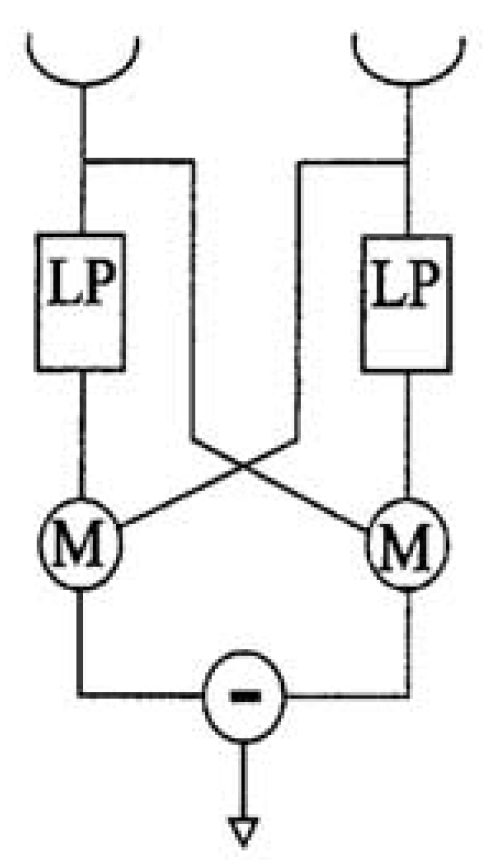

#### Frequency Response


$$R={\Delta I}^2 \frac{\;\tau_l \omega }{1+\tau_l^2 \omega^2 }\sin \left(\frac{2\pi \Delta \varphi }{\lambda }\right)$$


#### Buchner Frequency Response


$$R={\Delta I}^2 \frac{\;\pi \tau_l \frac{\omega }{\lambda }}{1+\tau_l^2 {\left(2\pi \frac{\omega }{\lambda }\right)}^2 }\sin \left(\frac{2\pi \Delta \varphi }{\lambda }\right)$$


R_freq_lp = I^(2)*((tau_l.*omega)./((1 + tau_l^(2)*omega.^(2)))).*sin(2*pi*phi/lambda)

$$R\_freq\_lp = \frac{{\text{I}}^{2}\,\omega \,\tau_{l}\,\sin\left(\frac{2\,\pi \,\phi }{\lambda }\right)}{\omega^{2}\,{\tau_{l}}^{2}+1}$$

R_freq_lp_B = I^(2)*((pi*tau_l.*omega/lambda)./((1 + tau_l^(2)*(2*pi*omega/lambda).^(2)))).*sin(2*pi*phi/lambda)

$$R\_freq\_lp\_B = \frac{\pi \,{\text{I}}^{2}\,\omega \,\tau_{l}\,\sin\left(\frac{2\,\pi \,\phi }{\lambda }\right)}{\lambda \,\left(\frac{4\,\omega^{2}\,{\tau_{l}}^{2}\,\pi^{2}}{\lambda^{2}}+1\right)}$$

#### Step Response


$$R={\Delta I}^2 \sin \left(\frac{2\pi \Delta \varphi }{\lambda }\right)\frac{\;\tau_l \omega }{1+\tau_l^2 \omega^2 }\left\lbrack 1+\mathrm{exp}\left(-\frac{t}{\tau_l }\right)\left(\tau_l \omega \;\mathrm{sin}\left(\omega t\right)-\mathrm{cos}\left(\omega t\right)\right)\right\rbrack$$


R_step_lp = I^(2).*sin(2*pi*phi/lambda).*(tau_l*omega./(1 + tau_l^(2)*omega.^(2)))*(1 + exp(-t/tau_l).*(tau_l*omega*sin(omega*t) - cos(omega*t)))

$$R\_step\_lp = -\frac{{\text{I}}^{2}\,\omega \,\tau_{l}\,\sin\left(\frac{2\,\pi \,\phi }{\lambda }\right)\,\left({\mathrm{e}}^{-\frac{t}{\tau_{l}}}\,\left(\cos\left(\omega \,t\right)-\omega \,\tau_{l}\,\sin\left(\omega \,t\right)\right)-1\right)}{\omega^{2}\,{\tau_{l}}^{2}+1}$$

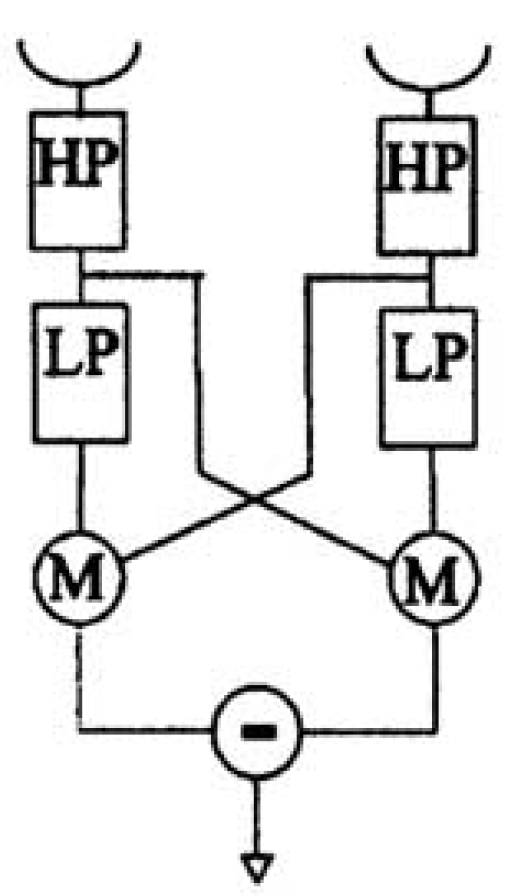

#### Frequency Response


$$R={\Delta I}^2 \frac{\;\tau_l \tau_h \omega^3 }{\left(1+\tau_l^2 \omega^2 \right)\left(1+\tau_h^2 \omega^2 \right)}\sin \left(\frac{2\pi \Delta \varphi }{\lambda }\right)$$


R_freq_lphp = I^(2)*((tau_l*tau_h^(2).*omega.^(3))./((1 + tau_l^(2)*omega.^(2)).*(1 + tau_h^(2)*omega.^(2)))).*sin(2*pi*phi/lambda)

$$R\_freq\_lphp = \frac{{\text{I}}^{2}\,\omega^{3}\,{\tau_{h}}^{2}\,\tau_{l}\,\sin\left(\frac{2\,\pi \,\phi }{\lambda }\right)}{\left(\omega^{2}\,{\tau_{h}}^{2}+1\right)\,\left(\omega^{2}\,{\tau_{l}}^{2}+1\right)}$$

#### Step Response


$$K=1+\omega^2 \tau_l \tau_h$$



$$F_1 =\tau_l \omega^2 \left(\tau_h -\tau_l \right)$$



$$F_2 =\omega \left\lbrack \left(\tau_h \tau_l \omega^2 +1\right)\tau_l \;\mathrm{exp}\left(-\frac{t}{\tau_l }\right)+\left(\tau_h -\tau_l \right)\;\mathrm{exp}\left(-\frac{t}{\tau_h }\right)\right\rbrack$$



$$F_3 =\tau_l \omega^2 \left(\tau_h -\tau_l \right)\;\exp \left(-\frac{t}{\tau_l }\right)+\left(\tau_h \tau_l \omega^2 +1\right)\;\exp \left(-\frac{t}{\tau_h }\right)$$



$$R={\Delta I}^2 \sin \left(\frac{2\pi \Delta \varphi }{\lambda }\right)\frac{\;\tau_h \omega }{\left(1+\tau_l^2 \omega^2 \right)\left(1+\tau_h^2 \omega^2 \right)}\left\lbrack K+F_1 \;\mathrm{exp}\left(-\frac{t}{\tau_l }\right)\exp \left(-\frac{t}{\tau_h }\right)+F_2 \mathrm{sin}\left(\omega t\right)-F_3 \mathrm{cos}\left(\omega t\right)\right\rbrack$$


K = 1 + omega^(2)*tau_l*tau_h;
F1 = tau_l*omega^(2)*(tau_h - tau_l);
F2 = omega*((tau_h*tau_l*omega^(2) + 1)*tau_l*exp(-t/tau_l) + (tau_h - tau_l)*exp(-t/tau_h));
F3 = tau_l*omega^(2)*(tau_h - tau_l)*exp(-t/tau_l) + (tau_h*tau_l*omega^(2) + 1)*exp(-t/tau_h);
% syms F1 F2 F3 K
R_step_lphp = I^(2).*sin(2*pi*phi/lambda).*(tau_h*omega./((1 + tau_l^(2)*omega.^(2))*(1 + tau_h^(2)*omega.^(2))))*(K + F1*exp(-t/tau_l)*exp(-t/tau_h) + F2*sin(omega*t) - F3*cos(omega*t))

$$R\_step\_lphp = \begin{array}{l} \frac{{\text{I}}^{2}\,\omega \,\tau_{h}\,\sin\left(\frac{2\,\pi \,\phi }{\lambda }\right)\,\left(\omega^{2}\,\tau_{h}\,\tau_{l}-\cos\left(\omega \,t\right)\,\left({\mathrm{e}}^{-\frac{t}{\tau_{h}}}\,\sigma_{1}+\omega^{2}\,\tau_{l}\,{\mathrm{e}}^{-\frac{t}{\tau_{l}}}\,\left(\tau_{h}-\tau_{l}\right)\right)+\omega \,\sin\left(\omega \,t\right)\,\left({\mathrm{e}}^{-\frac{t}{\tau_{h}}}\,\left(\tau_{h}-\tau_{l}\right)+\tau_{l}\,{\mathrm{e}}^{-\frac{t}{\tau_{l}}}\,\sigma_{1}\right)+\omega^{2}\,\tau_{l}\,{\mathrm{e}}^{-\frac{t}{\tau_{h}}}\,{\mathrm{e}}^{-\frac{t}{\tau_{l}}}\,\left(\tau_{h}-\tau_{l}\right)+1\right)}{\left(\omega^{2}\,{\tau_{h}}^{2}+1\right)\,\left(\omega^{2}\,{\tau_{l}}^{2}+1\right)}\\ \mathrm{where}\\ \sigma_{1}=\tau_{h}\,\tau_{l}\,\omega^{2}+1 \end{array}$$

# Simulations

### Frequency Response: Low-pass only , Wavelengh Variation , Interommatidial Span

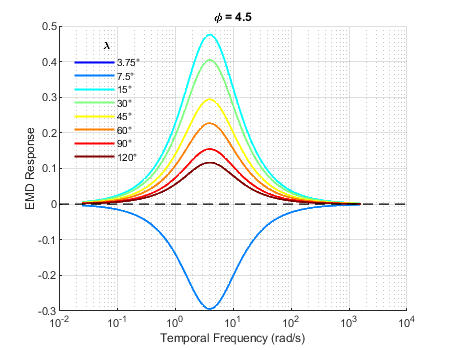

clear;close all;clc

I = 1;
tau_l = 40e-3;
%phi = [2,4.5,7,15];
phi = [4.5];
n_phi = length(phi);
lambda = 3.75*[1,2,4,8,12,16,24,32];
n_lambda = length(lambda);
omega = logspace(-0.8,4,500)';

clms = 1;
fig(1) = figure (1) ; clf ; cla
set(fig,'Position',1*[2 2 clms*450 ceil(n_phi/clms)*350],'Color','w')
ax = gobjects(n_phi,1);
for jj = 1:n_phi
    ax(jj) = subplot(ceil(n_phi/clms),clms,jj); hold on ; title(['\phi = ' num2str(phi(jj))])
    xlabel('Temporal Frequency (rad/s)')
    ylabel('EMD Response')
    set(ax(jj),'XScale','log')
    CC = jet(n_lambda);
    for kk = 1:n_lambda
        R = I^(2)*((tau_l.*omega)./((1 + tau_l^(2)*omega.^(2)))).*sin(2*pi*phi(jj)/lambda(kk));
        R = vpa(R,3);
        R = double(R);
        [mm,midx] = max(R);
        m_freq = omega(midx)/(2*pi);
        h.freq(kk) = plot(omega/(2*pi), R, 'Color', CC(kk,:), 'LineWidth', 1.5);
%         plot([m_freq m_freq], [0 mm], '--', 'Color', CC(kk,:), 'LineWidth', 1)
    end
    plot(ax(jj).XLim,[0 0],'--k', 'LineWidth', 1)
    if jj==1
        leg = legend(h.freq, strcat(string(lambda),char(176)), 'Location', 'NorthWest');
        leg.Box = 'off';
        leg.Title.String = '\lambda';
    end
end
set(ax,'FontSize',8)
set(ax,'XGrid','on','YGrid','on')
linkaxes(ax,'xy')

### Frequency Response: Low-pass only , Interommatidial Variation , Wavelengh Span

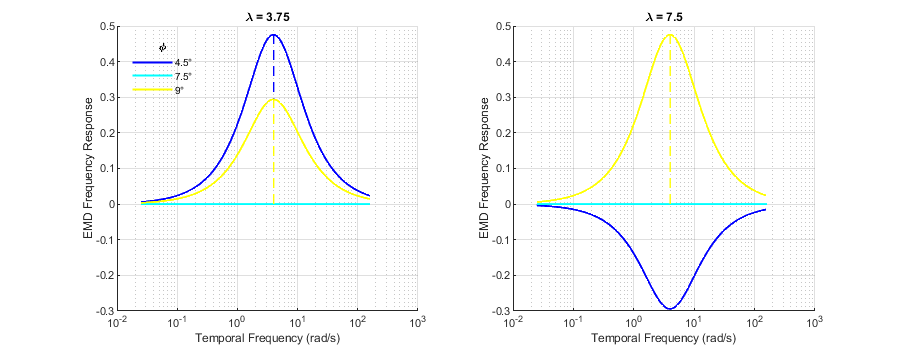

clear;close all;clc

I = 1;
tau_l = 40e-3;
%phi = [1,2,4.5,7.5,9,15,30];
phi = [4.5,7.5,9];
n_phi = length(phi);
%lambda = 3.75*[1,2,4.5*2/3.75,8,16];
lambda = 3.75*[1,2];
n_lambda = length(lambda);
omega = logspace(-0.8,3,500)';

clms = 2;
fig(1) = figure (2) ; clf ; cla
set(fig,'Position',1*[2 2 clms*450 ceil(n_lambda/clms)*350],'Color','w')
for kk = 1:n_lambda
    ax(kk) = subplot(ceil(n_lambda/clms),clms,kk); hold on ; title(['\lambda = ' num2str(lambda(kk))])
    xlabel('Temporal Frequency (rad/s)')
    ylabel('EMD Frequency Response')
    set(ax(kk),'XScale','log')
    plot([omega(1), omega(end)]/(2*pi),[0 0],'--k', 'LineWidth', 1)
    CC = jet(n_phi);
    for jj = 1:n_phi
        R = I^(2)*((tau_l.*omega)./((1 + tau_l^(2)*omega.^(2)))).*sin(2*pi*phi(jj)/lambda(kk));
        R = vpa(R,3);
        R = double(R);
        [mm,midx] = max(R);
        m_freq = omega(midx)/(2*pi);
        h.freq(jj) = plot(omega/(2*pi), R, 'Color', CC(jj,:), 'LineWidth', 1.5);
        plot([m_freq m_freq], [0 mm], '--', 'Color', CC(jj,:), 'LineWidth', 1)
    end
    if kk==1
        leg = legend(h.freq, strcat(string(phi),char(176)), 'Location', 'NorthWest');
        leg.Box = 'off';
        leg.Title.String = '\phi';
    end
end
set(ax,'FontSize',8)
set(ax,'XGrid','on','YGrid','on')
linkaxes(ax,'xy')

### Frequency Response: Low-pass only , Time Constant Variation , Wavelengh Span

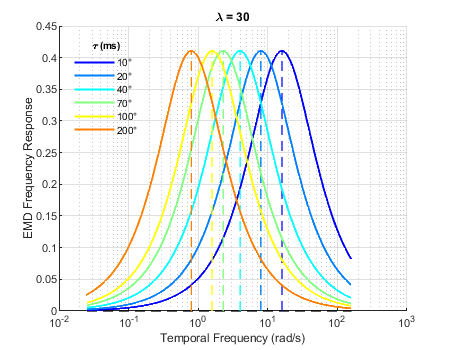

clear;close all;clc

I = 1;
tau_l = 10^(-3)*[10 20 40 70 100 200];
n_tau = length(tau_l);
phi = 4.6;
%lambda = 3.75*[1,2,4.6*2/3.75,8,16];
lambda = 3.75*[8];
n_lambda = length(lambda);
omega = logspace(-0.8,3,500)';

clms = 1;
fig(1) = figure (2) ; clf ; cla
set(fig,'Position',1*[2 2 clms*450 ceil(n_lambda/clms)*350],'Color','w')
for kk = 1:n_lambda
    ax(kk) = subplot(ceil(n_lambda/clms),clms,kk); hold on ; title(['\lambda = ' num2str(lambda(kk))])
    xlabel('Temporal Frequency (rad/s)')
    ylabel('EMD Frequency Response')
    set(ax(kk),'XScale','log')
    plot([omega(1), omega(end)]/(2*pi),[0 0],'--k', 'LineWidth', 1)
    CC = jet(n_tau);
    for jj = 1:n_tau
        R = I^(2)*((tau_l(jj).*omega)./((1 + tau_l(jj)^(2)*omega.^(2)))).*sin(2*pi*phi/lambda(kk));
        R = vpa(R,3);
        R = double(R);
        [mm,midx] = max(R);
        m_freq = omega(midx)/(2*pi);
        h.freq(jj) = plot(omega/(2*pi), R, 'Color', CC(jj,:), 'LineWidth', 1.5);
        plot([m_freq m_freq], [0 mm], '--', 'Color', CC(jj,:), 'LineWidth', 1)
    end
    if kk==1
        leg = legend(h.freq, strcat(string(1000*tau_l),char(176)), 'Location', 'NorthWest');
        leg.Box = 'off';
        leg.Title.String = '\tau (ms)';
    end
end
set(ax,'FontSize',8)
set(ax,'XGrid','on','YGrid','on')
linkaxes(ax,'xy')

#### Step Response

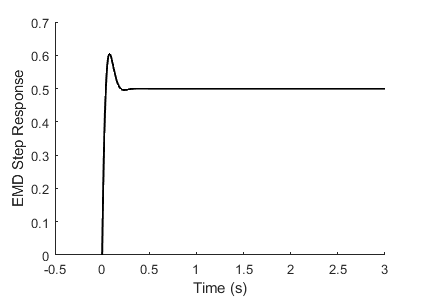

I = 1;
tau_l = 50e-3;
phi = 5;
lambda = 20;
omega = 20;
t = linspace(0,3,500)';

R = I^(2).*sin(2*pi*phi/lambda).*(tau_l*omega./(1 + tau_l^(2)*omega.^(2))).*(1 + exp(-t/tau_l).*(tau_l*omega*sin(omega*t) - cos(omega*t)));
R = vpa(R,3);
R = double(R);

fig(1) = figure (1) ; clf ; cla
set(fig,'Position',0.85*[2 2 500 350])
ax = subplot(1,1,1) ; hold on
xlabel('Time (s)')
ylabel('EMD Step Response')
plot(t, R, 'k', 'LineWidth', 1.5)
ax.XLim(1) = -0.5;

#### Frequency Response Buchner

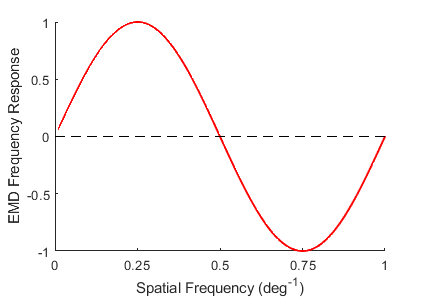

I = 1;
tau_l = 50e-3;
phi = 1;
lambda = linspace(0.05,100/phi,10000)';

k = 1;
omega = k*lambda;

R = I^(2)*((pi*tau_l.*omega./lambda)./((1 + tau_l^(2).*(2*pi*omega./lambda).^(2)))).*sin(2*pi*phi./lambda);
R = vpa(R,3);
R = double(R);
R = R./max(abs(R));

fig(1) = figure (1) ; clf ; cla
set(fig,'Position',0.85*[2 2 500 350])
ax = subplot(1,1,1) ; hold on
xlabel('Spatial Frequency (deg^{-1})')
ylabel('EMD Frequency Response')
plot(1./lambda, R, 'r', 'LineWidth', 1.5)
ax.XLim = [0 1/phi];
plot(ax.XLim,[0 0],'k--')
ax.YLim = 1.0*max(abs(ax.YLim))*[-1 1];
ax.XTick = 0:0.25:1;

% syms t d_t I I_0 omega phi lambda d_phi v A_h(omega) A_l(omega) Phi_h(omega) Phi_l(omega) tau_l tau_h
% d_t = d_phi/v;
% omega = 2*pi*v/lambda;
% x1 = I_0 + I*sin(omega*t + phi);
% x2 = I_0 + I*sin(omega*(t-d_t) + phi);
% L1 = I_0 + A_l(omega)*I*sin(omega*t + phi + Phi_l(omega));
% L2 = I_0 + A_l(omega)*I*sin(omega*t + phi + Phi_l(omega) - 2*pi*d_phi/lambda);
% H1 = I_0 + A_h(omega)*I*sin(omega*t + phi + Phi_l(omega));
% H2 = I_0 + A_h(omega)*I*sin(omega*t + phi + Phi_l(omega) - 2*pi*d_phi/lambda);